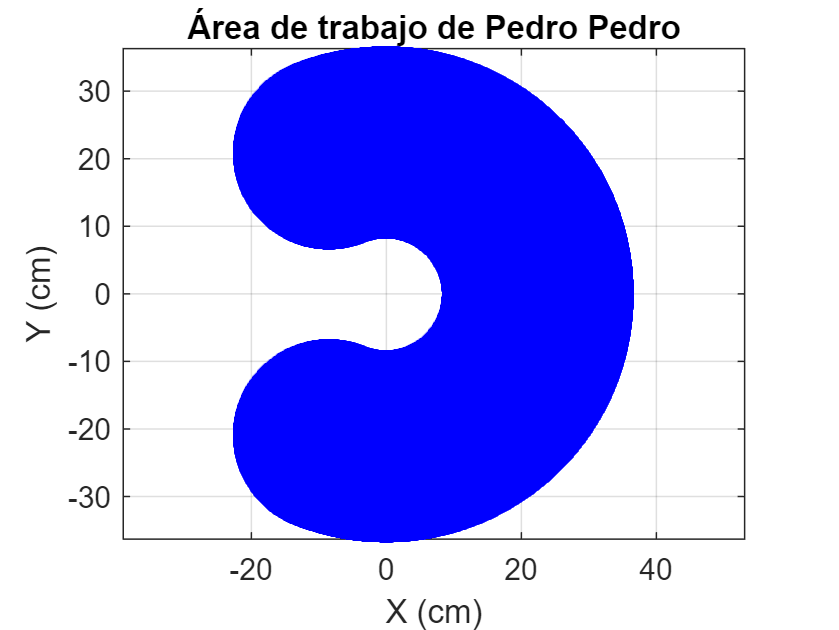

% Definición de los parámetros
L1 = 22.5; % Longitud del primer eslabón en cm
L2 = 13.8; % Longitud del segundo eslabón en cm
theta1_range = linspace(deg2rad(-112), deg2rad(112), 105); % Rango de theta1
theta2_range = linspace(deg2rad(-360), deg2rad(360), 800); % Rango de theta2

% Preparación de los datos para graficar
[X, Y] = meshgrid(theta1_range, theta2_range); % Rejilla de valores de theta1 y theta2
X_end = L1 * cos(X) + L2 * cos(X + Y); % X final del extremo del manipulador
Y_end = L1 * sin(X) + L2 * sin(X + Y); % Y final del extremo del manipulador

% Graficando el resultado
figure;
plot(X_end, Y_end, 'b.');
title('Área de trabajo de Pedro Pedro');
xlabel('X (cm)');
ylabel('Y (cm)');
axis equal;
grid on;